%% ensamble from the fault injection with different simin(fault param)
mdl = bdroot

mdl = 'MOBATSim'

location = fullfile(pwd,'data_w_label')

location = 'C:\matlabWS\MOBATSim\data_w_label'

warning off
% noise_factor=1;
% noiseGain=20;


% config simin
stuck_array = linspace(0,2,2); %0,8,20
noise_array = linspace(0,0.2,2);%0,0.8,2
[stuckDuration,noisePower] = ...
    ndgrid(stuck_array,noise_array)

stuckDuration =      0     0
     2     2


noisePower =          0    0.2000
         0    0.2000


clear simin

for ct = numel(stuckDuration):-1:1
    
tmp = Simulink.SimulationInput(mdl);
tmp = setVariable(tmp,'stuckDuration',stuckDuration(ct));
tmp = setVariable(tmp,'noisePower',noisePower(ct));
simin(ct) = tmp;
end
simin

simin =   1×4 SimulationInput array with properties:

    ModelName
    InitialState
    ExternalInput
    ModelParameters
    BlockParameters
    Variables
    PreSimFcn
    PostSimFcn
    UserString


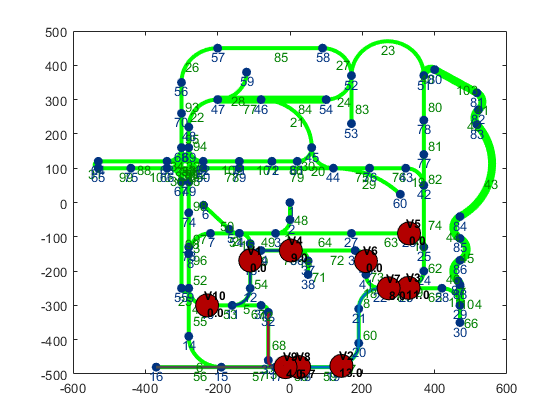

[06-Mar-2022 12:23:22] Running simulations...


[06-Mar-2022 12:25:06] Completed 1 of 4 simulation runs


[06-Mar-2022 12:25:35] Completed 2 of 4 simulation runs. Run 2 has errors.


[06-Mar-2022 12:26:02] Completed 3 of 4 simulation runs. Run 3 has errors.


[06-Mar-2022 12:26:31] Completed 4 of 4 simulation runs. Run 4 has errors.



% sim run
prepare_simulator("scenarioName","Convoy Platoons");

[status,E] = generateSimulationEnsemble(simin,location);

ensemble = simulationEnsembleDatastore(location);
ensemble.DataVariables

ans = 2×1 string array
    "SimulationMetadata"
    "logsout"


ensemble

ensemble =   simulationEnsembleDatastore with properties:

           DataVariables: [2×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [2×1 string]
                ReadSize: 1
              NumMembers: 4
          LastMemberRead: [0×0 string]
                   Files: [4×1 string]



% read data ensemble
ensemble.SelectedVariables = ["logsout"];
ensemble.ReadSize = 5;
data = read(ensemble)% get a table

data = 4×1 table
                   logsout               
    _____________________________________

    {1×1 Simulink.SimulationData.Dataset}
    {1×1 Simulink.SimulationData.Dataset}
    {1×1 Simulink.SimulationData.Dataset}
    {1×1 Simulink.SimulationData.Dataset}


dataCell = table2cell(data)

dataCell = 4×1 cell array
    {1×1 Simulink.SimulationData.Dataset}
    {1×1 Simulink.SimulationData.Dataset}
    {1×1 Simulink.SimulationData.Dataset}
    {1×1 Simulink.SimulationData.Dataset}
